# Load Massive Data File

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\');
latestSweep = latestTimeParse(inputPath,'megaSweep');
tic
%Takes about 2 minutes
load(latestSweep)
toc

Elapsed time is 125.925999 seconds.


clear inputPath latestSweep


# Load Sweep Params for Easy Indexing

%This will go away after next run - will package them into the structure
inputPath = strcat(commonPath,'\Performance Input Signals\');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestPureSin)
clear inputPath latestPureSin

decimationFactor = 5;
sinfreqsDecimate = sinfreqs(1:decimationFactor:end);
Kp = .1:1:20;
Ki = .1:1:20;
switchThresh = 0:0.5:5;

# Plot some stuff

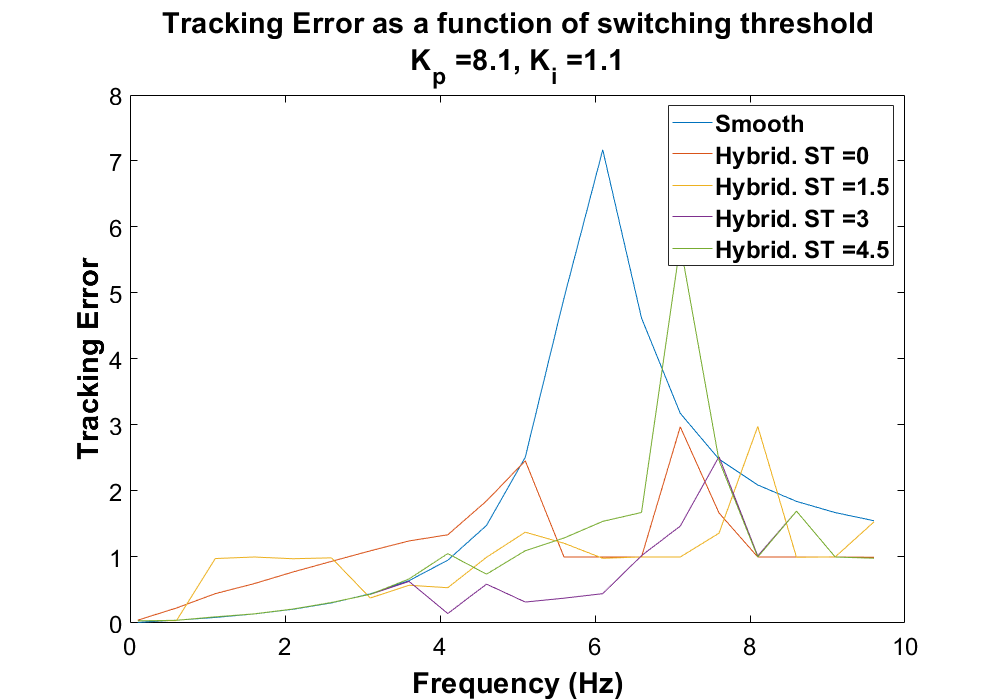

easyPlotter('increasingSwitchThresh','Kp',8,'Ki',1,sweepData,Kp,Ki,switchThresh,...
    sinfreqsDecimate,pureSinTime,5)

# Plot some other stuff

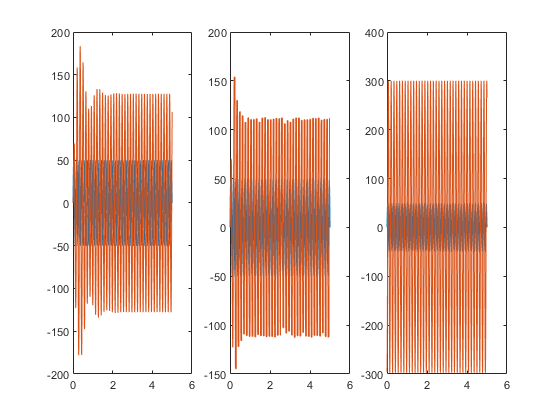

kpIndex = 9

kiIndex = 2

stIndex = 10

fIndex = 15

[kpIndex,kiIndex,stIndex,fIndex] = responsePlot(Kp,Ki,switchThresh,...
    sinfreqsDecimate,8,1,4.5,7.1,pureSinTime,sweepData)

sweepData(kpIndex,kiIndex,stIndex,fIndex)

ans = struct with fields:
              Kp: 8.1000
              Ki: 1.1000
    switchThresh: 4.5000
       inputFreq: 7.1000
          sError: 3.1774
          hError: 5.7380
       smoothOut: [5001×1 double]
       hybridOut: [1×5001 double]
           sGain: 2.5354
          sPhase: 4.1584
           hGain: 5.9469
          hPhase: -1.2773
            hFit: [1×5001 double]
         rsquare: -0.8246


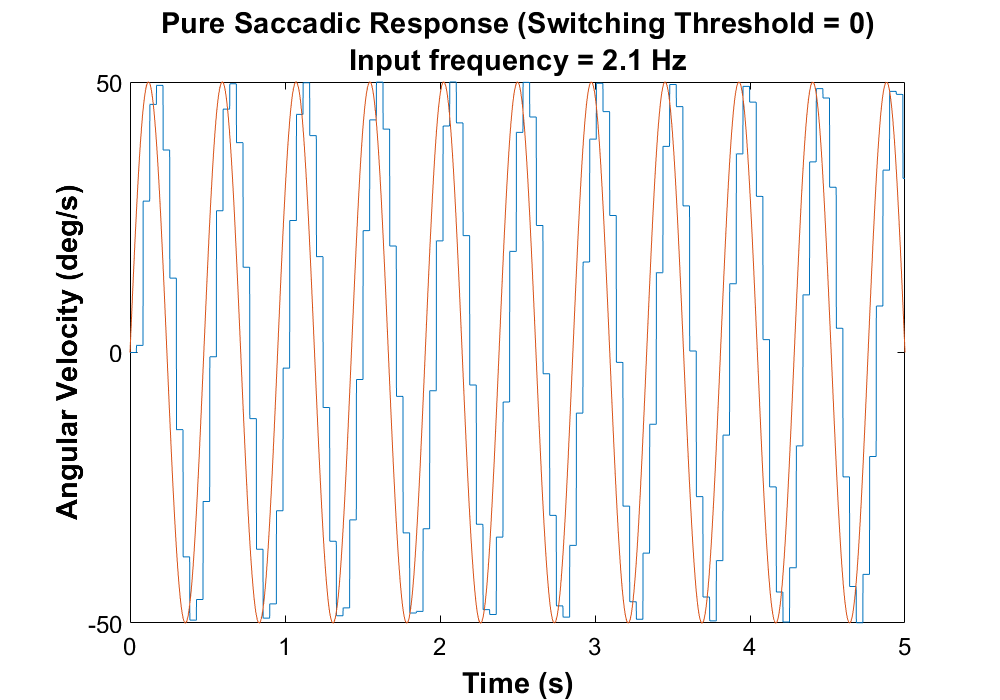

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,1,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Pure Saccadic Response (Switching Threshold = 0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

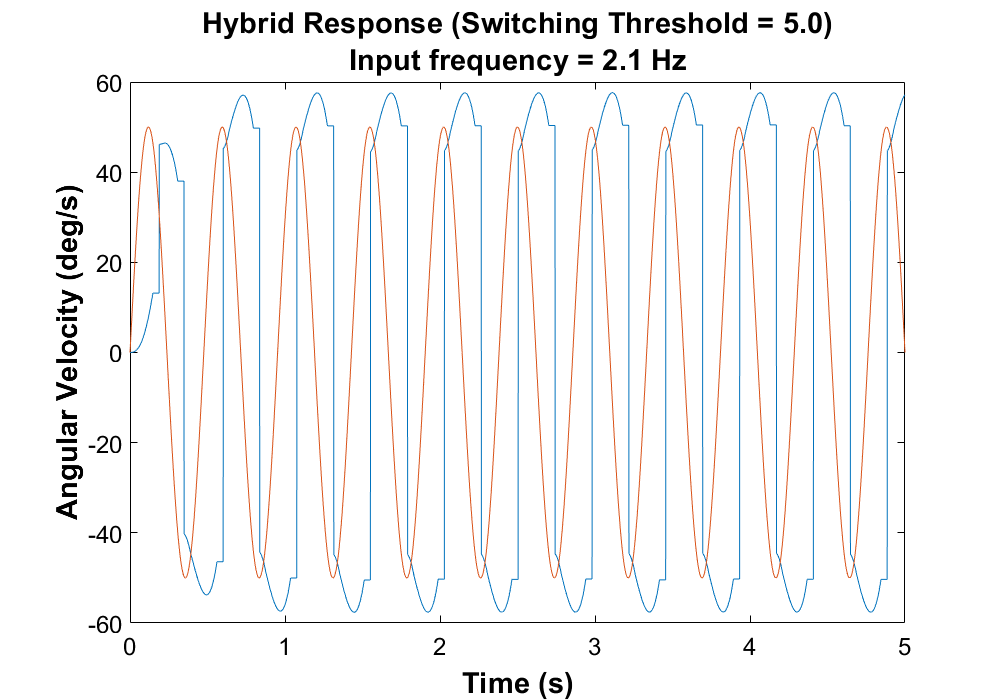


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(1,10,11,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response (Switching Threshold = 5.0)','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

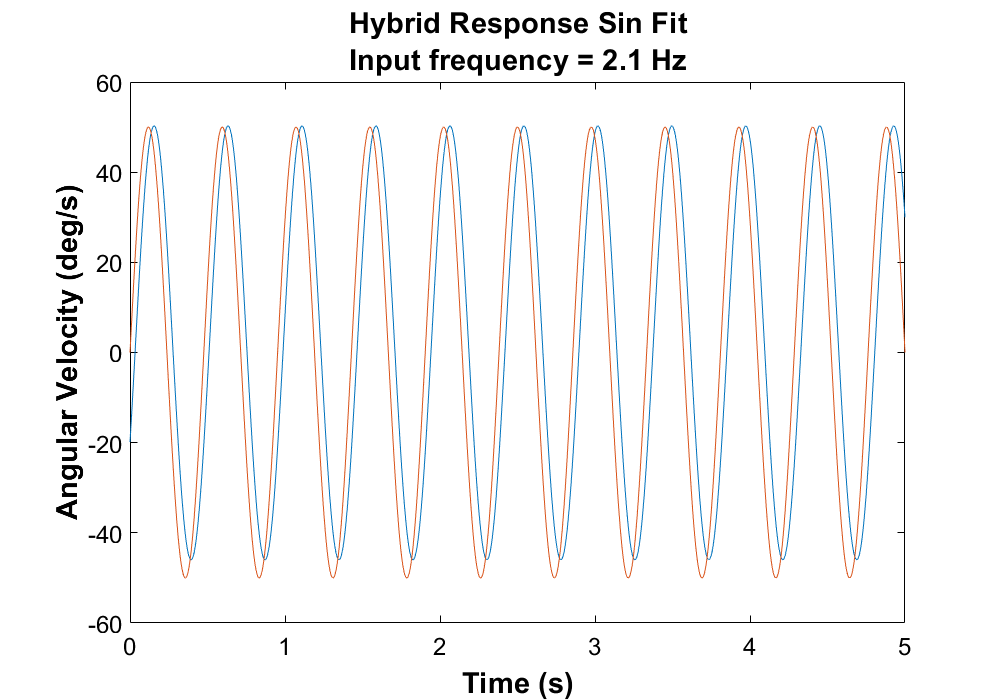


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(5,5,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hFit,pureSinTime,sinin)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response Sin Fit','Input frequency = 2.1 Hz'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

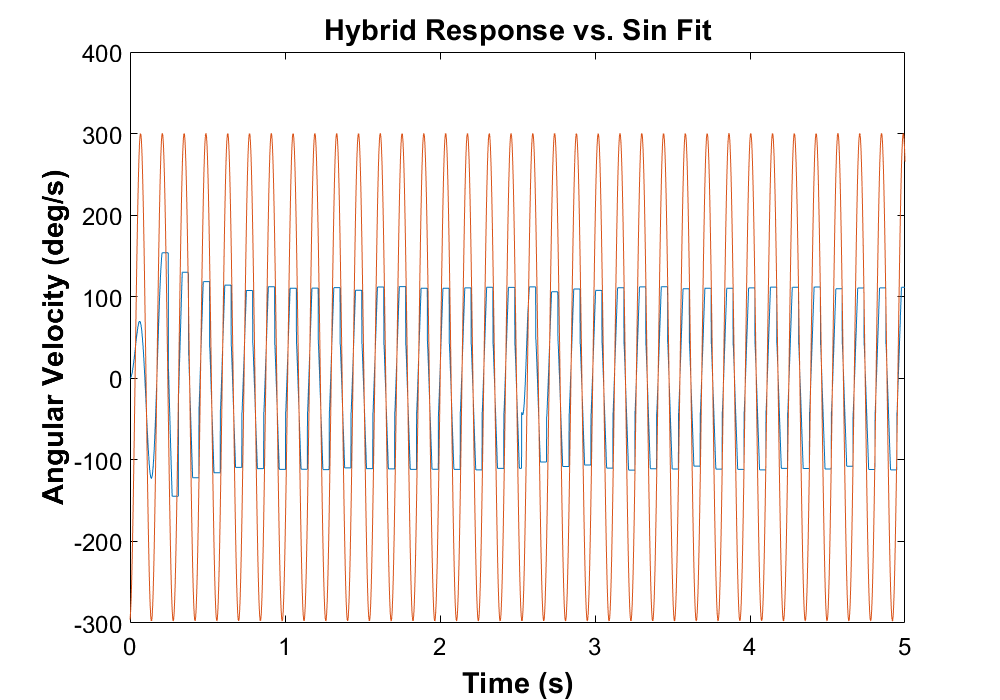


figure('Renderer', 'painters', 'Position', [10 10 1000 700])
chosenPoint = sweepData(9,2,10,15);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
plot(pureSinTime,chosenPoint.hybridOut,pureSinTime,chosenPoint.hFit)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Hybrid Response vs. Sin Fit'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')

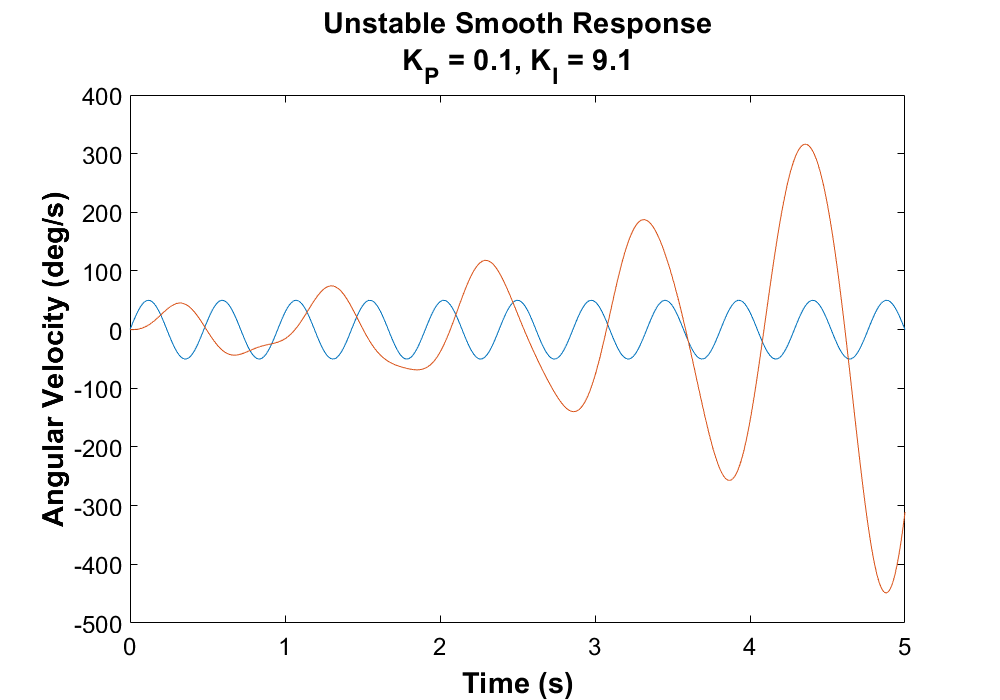



chosenPoint = sweepData(1,10,4,5);
sinin = 50*sin(2*pi*chosenPoint.inputFreq*pureSinTime);
C_tf = tf([0.1 9.1],[1 0]);

%Delay (Pade approximation)
td =.04;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant;
den = (1 + num*d_tf);
cl_tf = num/den;

unstable = lsim(cl_tf,sinin,pureSinTime);

figure('Renderer', 'painters', 'Position', [10 10 1000 700])
plot(pureSinTime,sinin,pureSinTime,unstable)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 18;
ax.XAxis.FontName = 'Helvetica';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 18;
ax.YAxis.FontName = 'Helvetica';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
ylabel('Angular Velocity (deg/s)','FontName','Helvetica','FontSize',22,'FontWeight','bold')
title({'Unstable Smooth Response','K_P = 0.1, K_I = 9.1'},'FontName','Helvetica','FontSize',22,'FontWeight','bold')